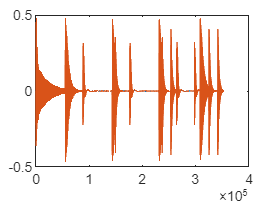

%monoljud KOM IHÅG

[y1,Fs] = audioread("AnalogRytm_120BPM.wav");
[y2,Fs] = audioread("TimeFactor_RE501_120BPM.wav");
plot(y1)

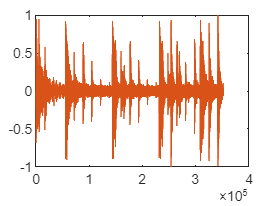

plot(y2)


% Spectrogram
window = 512;
noverlap = 256;
nfft = 0;
%spectrogram(y1(:,1),window,noverlap,"yaxis");

%ylim([0 0.2]);

%delay
zerodelay = zeros(16200,2);
delay1 = cat(1,zerodelay,y1);
org = cat(1, y1, zerodelay);

delay = ((delay1/2)+org);


%lowpass

delay = lowpass(delay,3000,Fs);

%reverb
reverbTime = 90;
gain = 0.7;
signalForReverb = delay;

for i = 0:2
 reverbLength = ceil((reverbTime/1000)*Fs / (3^i));
 signalForReverb = [signalForReverb;zeros(abs(reverbTime/100)*Fs,2)];

  b = zeros(1, reverbLength+1);
    b(1) = -gain;
    b(reverbLength+1) = 1;
    
    a = zeros(1, reverbLength+1);
    a(1) = 1;
    a(reverbLength+1) = -gain;
    
 signalForReverb = filter(b, a,signalForReverb);
end
delay = cat(1, delay, zeros(length(signalForReverb(:,1))-length(org(:,1)),2));
signalForReverb = lowpass(signalForReverb,5000, Fs);

reverbResult = (delay + signalForReverb*0.4);

% Dist

distLevel = 2;
distSound = (distLevel*reverbResult)./(1+distLevel*abs(reverbResult));

%Compress

for i=1:length(reverbResult)
        aboVal = max(abs(reverbResult(i,1)), abs(reverbResult(i,2)));
        reverbResult(i,1) = reverbResult(i,1) * (2 - aboVal);
        reverbResult(i,2) = reverbResult(i,2) * (2 - aboVal);
    end


plot(y2)

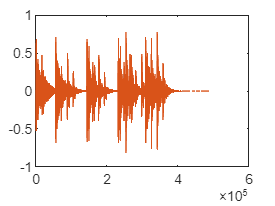

plot(reverbResult)

sound(y2,Fs)